## preparations

close all;
clc;
clear all;


% Sample data
%texture = load('C:\Program Files\MATLAB\R2023a\toolbox\images\imdata\cell.tif');
%f = texture.f;
f=imread('C:\Program Files\MATLAB\R2023a\toolbox\images\imdata\cell.tif');

f = 159×191 uint8 matrix
   118   116   112   111   114   118   124   132   162   192   194   180   161   130    95    84    95   124   153   167   168   156   135   116   109   114   121   121   114   105    99    92    95   110   125   127   123   119   108   101   108   123   131   143   164   169   153   133   131   133
   117   119   114   108   110   115   125   152   186   194   183   166   144   112    83    71    75    96   133   160   158   142   123   111   110   116   117   115   109   100    95    97   105   115   126   132   130   121   108   102   111   119   114   113   121   125   121   124   132   130
   115   116   114   108   109   114   135   173   185   170   147   135   127   113    92    76    74    90   126   160   156   132   113   109   108   107   104   107   118   118   109   107   109   113   119   124   123   116   110   113   128   142   142   133   122   107    97   100   112   117
   114   112   108   108   112   121   155   188   182   159   138   131

### Step 1

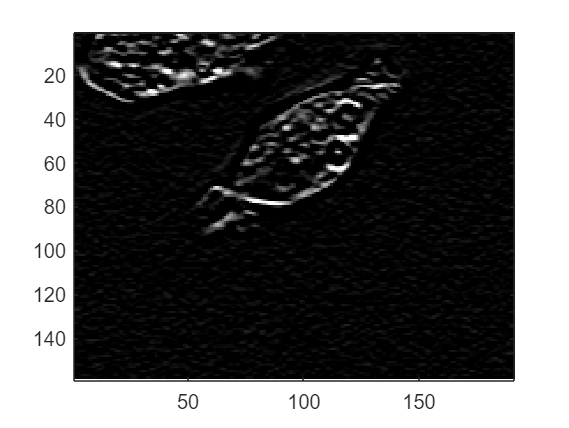

hsobel = fspecial('sobel');
filteredSobel  = imfilter(f,hsobel);
figure('Name', 'Sobel image');
imagesc(filteredSobel);
colormap gray;

### Step 2

% parameters:
alpha = 5000;       % bandwidth constraint
tau = 0.25;         % Lagrangian multipliers dual ascent time step
K = 4;              % number of modes
DC = 1;             % includes DC part (first mode at DC)

init = 1;           % initialize omegas randomly, may need multiple runs!

tol = K*10^-6;      % tolerance (for convergence)
[u, u_hat, omega] = VMD_2D(f, alpha, tau, K, DC, init, tol);

Me0 = adapthisteq(u(:,:,1));

### Step 3

Pkm = zeros(size(u(:,:,1)));
for k=2:K
     mf=medfilt2(u(:,:,k));
     Pkm = Pkm + mf;
end


## Visualization

figure('Name', 'Input image');
imagesc(f);
colormap gray;
axis equal;
axis off;

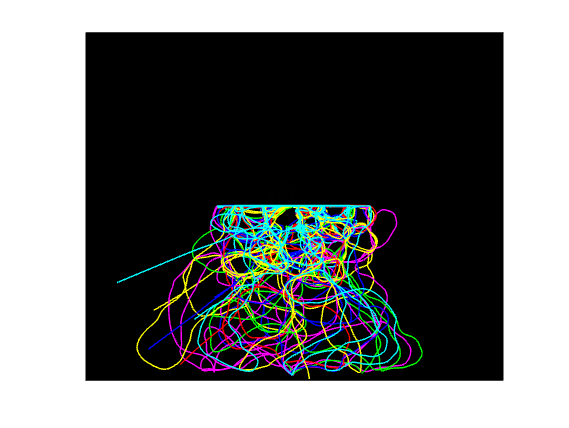


figure('Name', 'Input spectrum');
imagesc(abs(fftshift(fft2(f))));
colormap gray;
axis equal;
axis off;
hold on;
colors = 'rbycmg';
if(size(omega,3)>length(colors))
    for i=1:ceil(size(omega,3)/length(colors))
        colors = strcat(colors,'rbycmg');
    end
end
for k = 1:size(omega,3)
    plot( size(f,2)*(0.5+omega(:,1,k)), size(f,1)*(0.5+omega(:,2,k)), colors(k) );
end

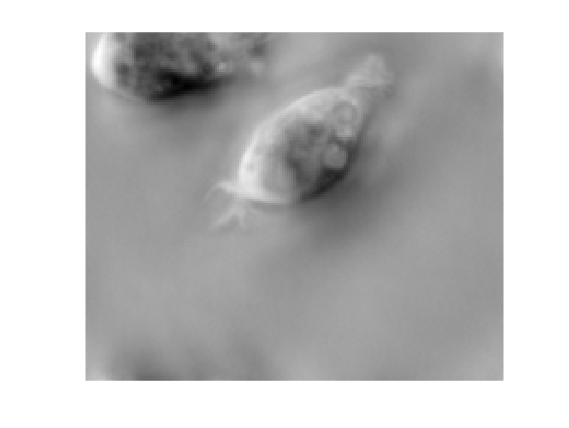

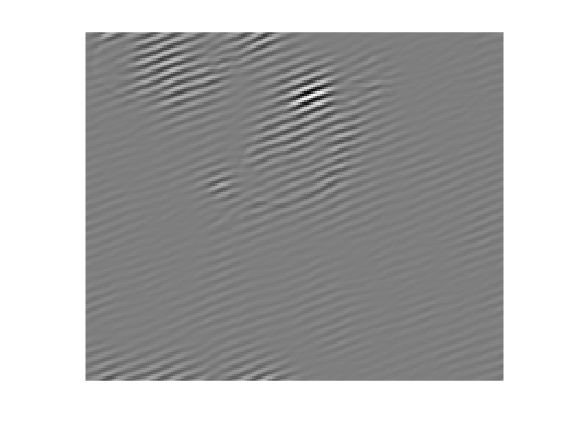

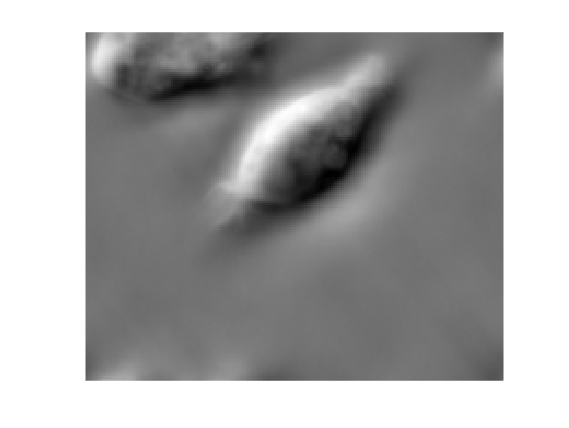

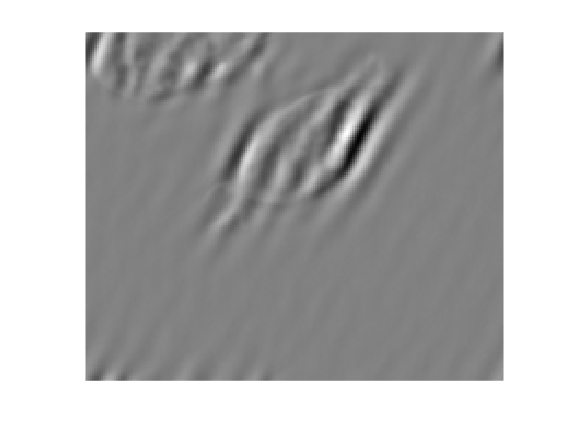

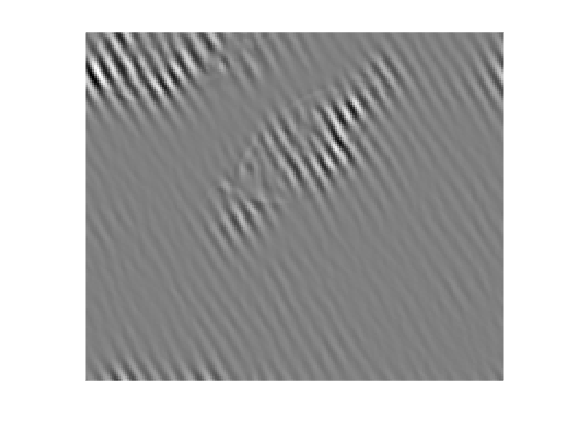

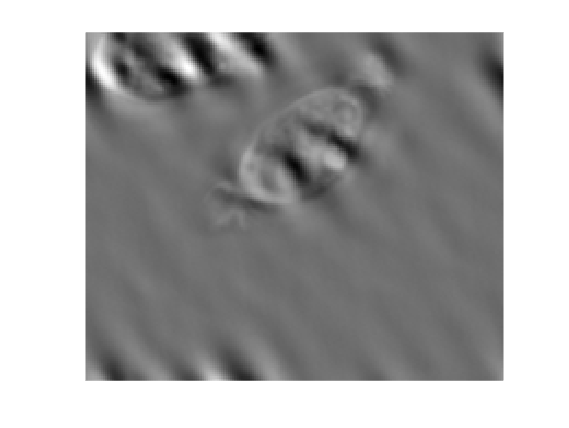

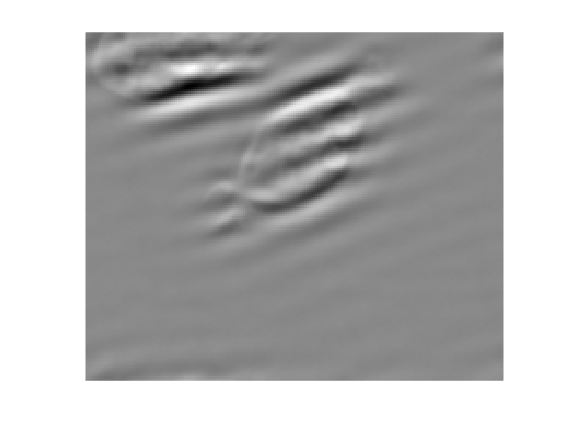

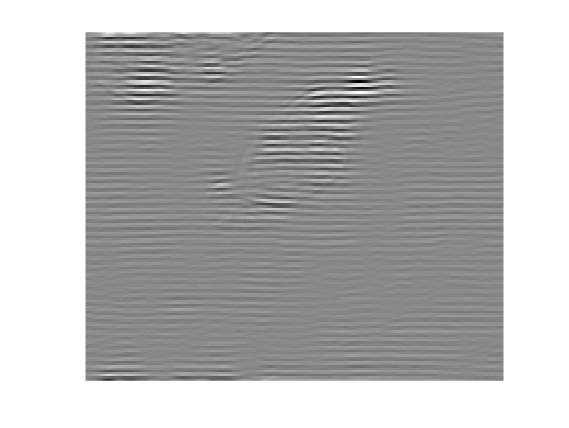


for k=1:size(u,3)
    figure('Name', ['Mode #' num2str(k)]);
    imagesc(u(:,:,k));
    colormap gray;
    axis equal;
    axis off;
end

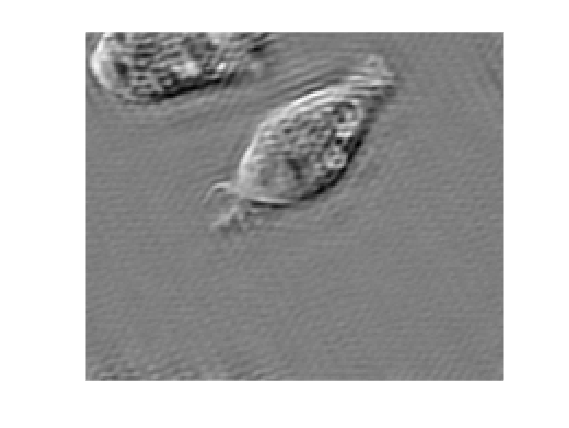


figure('Name', 'Reconstructed composite');
imagesc(sum(u,3));
colormap gray;
axis equal;
axis off;

function G=sobel(I)
    Gx=[-1 0 1;-2 0 2; -1 0 1]*I;
    Gy=[-1 -2 -1;0 0 0; 1 2 1]*I;
    G = sqrt(Gx^2 + Gy^2);
end